# Exercicis full 1

1. Escriviu un script que calculi 1 + 2 + ··· + n per a diferents valors de n.

clear vars;
n = 10;
sum(1:10)

ans =     55


2. Escriviu un script que calculi 1 p + 2p + · · · + n p per a diferents valors de n i p.

clear vars;
n = 10;
p = 2;
sum((1:n).^p)

ans =    385


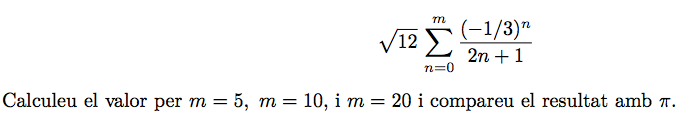

f5(5)

ans =           20.4496039790745


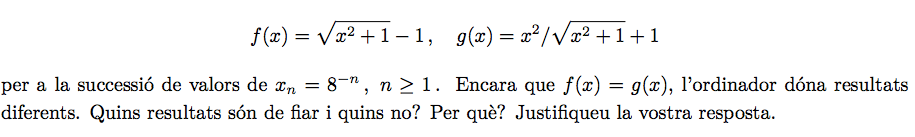

clear vars;
n = 15;
k = 1:n;
xn = 8.^(-k);
f8 = @(x) sqrt(x.^2 + 1) - 1;
g8 = @(x) x.^2 ./ (sqrt(x.^2 + 1) + 1);
format short g
[k;xn;f8(xn);g8(xn)]'

ans =             1        0.125    0.0077822    0.0077822
            2     0.015625   0.00012206   0.00012206
            3    0.0019531   1.9073e-06   1.9073e-06
            4   0.00024414   2.9802e-08   2.9802e-08
            5   3.0518e-05   4.6566e-10   4.6566e-10
            6   3.8147e-06    7.276e-12    7.276e-12
            7   4.7684e-07   1.1369e-13   1.1369e-13
            8   5.9605e-08   1.7764e-15   1.7764e-15
            9   7.4506e-09            0   2.7756e-17
           10   9.3132e-10            0   4.3368e-19


La funció g8 és més fiable que la funció f8, degut a la limitació dels bits de la mantissa dels registres.

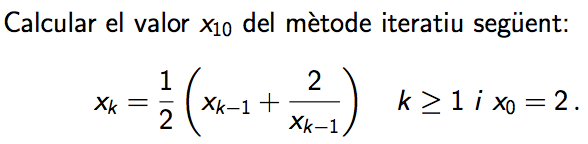

#### Bucle for

clear vars;
n = 10;
x = zeros(1,n+1);
x0 = 2;
x(1) = 2;
for k = 1:n
    x(k+1) = (1/2) * (x0 + (2/x0));
    x0 = x(k+1);
end
x

x =             2          1.5       1.4167       1.4142       1.4142       1.4142       1.4142       1.4142       1.4142       1.4142       1.4142


A = [(0:n);x;abs(x-sqrt(2));abs((x-sqrt(2))/sqrt(2))]';
T = array2table(A, 'VariableNames', {'n', 'Xn', 'absolut', 'relatiu'});
T

T = 11×4 table
    n       Xn       absolut       relatiu  
    __    ______    __________    __________

     0         2       0.58579       0.41421
     1       1.5      0.085786       0.06066
     2    1.4167     0.0024531     0.0017346
     3    1.4142    2.1239e-06    1.5018e-06
     4    1.4142    1.5947e-12    1.1276e-12
     5    1.4142    2.2204e-16    1.5701e-16
     6    1.4142    2.2204e-16    1.5701e-16
     7    1.4142    2.2204e-16    1.5701e-16
     8    1.4142    2.2204e-16    1.5701e-16
     9    1.4142    2.2204e-16    1.5701e-16
    10    1.4142    2.2204e-16    1.5701e-16


#### Bucle while

clear vars;
n = 10;
x = zeros(1,n+1);
x0 = 2;
x(1) = 2;
k = 1;
while k <= n
    x(k+1) = (1/2) * (x0 + (2/x0));
    x0 = x(k+1);
    k = k + 1;
end
x

x =             2          1.5       1.4167       1.4142       1.4142       1.4142       1.4142       1.4142       1.4142       1.4142       1.4142


A = [(0:n);x;abs(x-sqrt(2));abs((x-sqrt(2))/sqrt(2))]';
T = array2table(A, 'VariableNames', {'n', 'Xn', 'absolut', 'relatiu'});
T

T = 11×4 table
    n       Xn       absolut       relatiu  
    __    ______    __________    __________

     0         2       0.58579       0.41421
     1       1.5      0.085786       0.06066
     2    1.4167     0.0024531     0.0017346
     3    1.4142    2.1239e-06    1.5018e-06
     4    1.4142    1.5947e-12    1.1276e-12
     5    1.4142    2.2204e-16    1.5701e-16
     6    1.4142    2.2204e-16    1.5701e-16
     7    1.4142    2.2204e-16    1.5701e-16
     8    1.4142    2.2204e-16    1.5701e-16
     9    1.4142    2.2204e-16    1.5701e-16
    10    1.4142    2.2204e-16    1.5701e-16


#### Exercici 2

clear vars;
n = 20;
x = zeros(1,n);
x(1) = 1;
for k = 1:n
    x(k+1) = x(k) + (1 / factorial(k));
end
x

x =             1            2          2.5       2.6667       2.7083       2.7167       2.7181       2.7183       2.7183       2.7183       2.7183       2.7183       2.7183       2.7183       2.7183       2.7183       2.7183       2.7183       2.7183       2.7183       2.7183


A = [(0:n);x;abs(x-exp(1));abs((x-exp(1))/exp(1))]';
T = array2table(A, 'VariableNames', {'n', 'Xn', 'absolut', 'relatiu'});
T

T = 21×4 table
    n       Xn       absolut       relatiu  
    __    ______    __________    __________

     0         1        1.7183       0.63212
     1         2       0.71828       0.26424
     2       2.5       0.21828      0.080301
     3    2.6667      0.051615      0.018988
     4    2.7083     0.0099485     0.0036598
     5    2.7167     0.0016152    0.00059418
     6    2.7181    0.00022627    8.3241e-05
     7    2.7183     2.786e-05    1.0249e-05
     8    2.7183    3.0586e-06    1.1252e-06
     9    2.7183    3.0289e-07    1.1143e-07
    10    2.7183    2.7313e-08    1.0048e-08
    11    2.7183    2.2606e-09    8.3161e-10
    12    2.7183    1.7288e-10    6.3598e-11
    13    2.7183    1.2286e-11    4.5198e-12
    14    2.7183    8.1535e-13    2.9995e-13
    15    2.7183    5.0626e-14    1.8624e-14


# Polinomis en MatLab

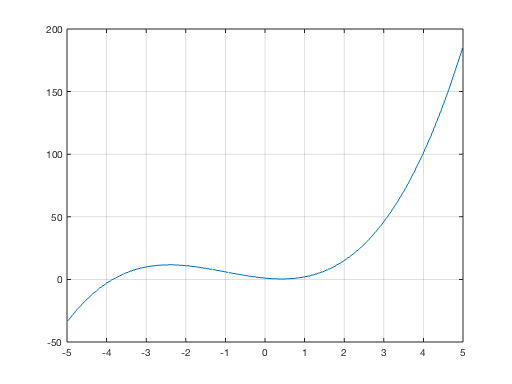

clear vars;
% polinomi x^3 + 3x^2 - 3x+1
p = [1 3 -3 1];
x = linspace(-5,5,50);
y = polyval(p,x);
plot(x,y),grid

roots(p)

ans =       -3.8473 +          0i
      0.42366 +    0.28361i
      0.42366 -    0.28361i


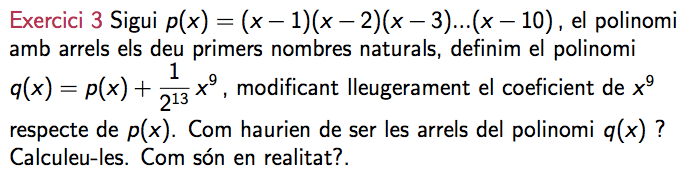

clear vars;
r = 1:20;
p = poly(r); p'

ans =             1
         -210
        20615
  -1.2568e+06
   5.3328e+07
  -1.6723e+09
   4.0172e+10
  -7.5611e+11
    1.131e+13
  -1.3559e+14


q = p;
q(2) = q(2) + 1/(2^13);
format long g
q'

ans =                          1
         -209.999877929688
                     20615
                  -1256850
                  53327946
               -1672280820
               40171771630
             -756111184500
            11310276995381
          -135585182899530


roots(q)

ans =            24.6376279826269 +      3.48944675212659i
           24.6376279826269 -      3.48944675212659i
           19.3146450015657 +      6.98804868664797i
           19.3146450015657 -      6.98804868664797i
           14.4469951843232 +      6.42254688582558i
           14.4469951843232 -      6.42254688582558i
           11.3914461708777 +       4.6793989841282i
           11.3914461708777 -       4.6793989841282i
           9.47371357204968 +      2.96985612121138i
           9.47371357204968 -      2.96985612121138i


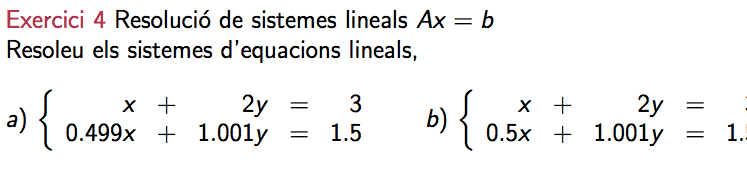

clear vars;
A = [1 2;0.499 1.001];
b = [3;1.5];
solA = A\b

solA =          0.999999999999852
          1.00000000000007


inv(A)*b

ans =          0.999999999999886
          1.00000000000006



B = [1 2;0.5 1.001];
a = [3;1.5];
solB = B\a

solB =      3
     0


inv(B)*a

ans =      3
     0



cond(A), cond(B)

ans =           2083.66685341034


ans =           6252.00084005161


function res = f5(m)
res = 0;
n = 0;
for i = n:m
    res = res + (((-1/3)^i)/2*i+1);
end
res = sqrt(12) * res;
end